# Results: Basic Psychometrics & Fixation Properties

## Housekeeping

The mat file loaded in, below, contains 3 tables:

- psychometrics: data for psychometric analyses

- initialFix: data relating to the intitial fixation analysis

- middleFix: data relating to middle fixation analyses

% clear workspace
clear;close all; clc
% load in data
load BasicPsychometrics_GazeProperties.mat
rng(56,'twister') % random seed, for replicability

## Basic Psychometrics

### Analysis

#### Choice Performance

Explain choice behavior as a function of the value difference between each item.

Variables

- chosen = which target was chosen (1 = left, 0 = right)

- vDiff = left value- right value

- monk = monkey identifier

% run mixed effects model
choice = fitglme(psychometrics,'chosen ~ vDiff + (vDiff|monk)','Distribution','Binomial')

choice = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30357
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                3
    Distribution                    Binomial
    Link                            Logit 
    FitMethod                       MPL   

Formula:
    chosen ~ 1 + vDiff + (1 + vDiff | monk)

Model fit statistics:
    AIC           BIC           LogLikelihood    Deviance  
    1.6432e+05    1.6436e+05    -82156           1.6431e+05

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat      DF       pValue      Lower       Upper     
    {'(Intercept)'}        -0.11564    0.059102    -1.9566    30355    0.050408    -0.23148    0.00020569
    {'vDiff'      }          1.3582    0.014761     92.012    30355           0      1

% run anova on the output of the model
choiceAnova = anova(choice)

choiceAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue  
    {'(Intercept)'}        3.8281    1      30355    0.050408
    {'vDiff'      }        8466.2    1      30355           0


#### Reaction Time

Explain reaction time behavior as a function of trial difficulty

Variables

- liftRT = reaction time (target onset-center lever lift)

- diffic = abs(left value- right value)

- monk = monkey identifier

% Mixed effects model
rt = fitglme(psychometrics,'liftRT ~ diffic + (diffic|monk)','Distribution','Normal')

rt = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30357
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    liftRT ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -36801    -36751    18407            -36813  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF       pValue       Lower        Upper   
    {'(Intercept)'}          0.88882      0.01073     82.832    30355            0      0.86779     0.90985
    {'diffic'     }        -0.034773    0.0026594    -13.076    30355    5.789e-39    -0.039985    -0.02

% run anova on the output of the model
rtAnova = anova(rt)

rtAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue   
    {'(Intercept)'}        6861.1    1      30355            0
    {'diffic'     }        170.97    1      30355    5.789e-39


#### Number of Fixations

Explain the number of fixations per trial as a function of trial difficulty

Variables

- totFix = total number of fixations in each  trial

- diffic = abs(left value- right value)

- monk = monkey identifier

% Mixed effects model
fix = fitglme(psychometrics,'totFix ~ diffic + (diffic|monk)','Distribution','Normal')

fix = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30357
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    totFix ~ 1 + diffic + (1 + diffic | monk)

Model fit statistics:
    AIC      BIC      LogLikelihood    Deviance
    64005    64055    -31996           63993   

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE          tStat     DF       pValue        Lower       Upper    
    {'(Intercept)'}          2.7124    0.042624    63.635    30355             0      2.6288       2.7959
    {'diffic'     }        -0.10999     0.00856    -12.85    30355    1.0852e-37    -0.12677    -0.093214



% run anova on the output of the model
fixAnova = anova(fix)

fixAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        4049.4    1      30355             0
    {'diffic'     }        165.11    1      30355    1.0852e-37


### Visualization of Results

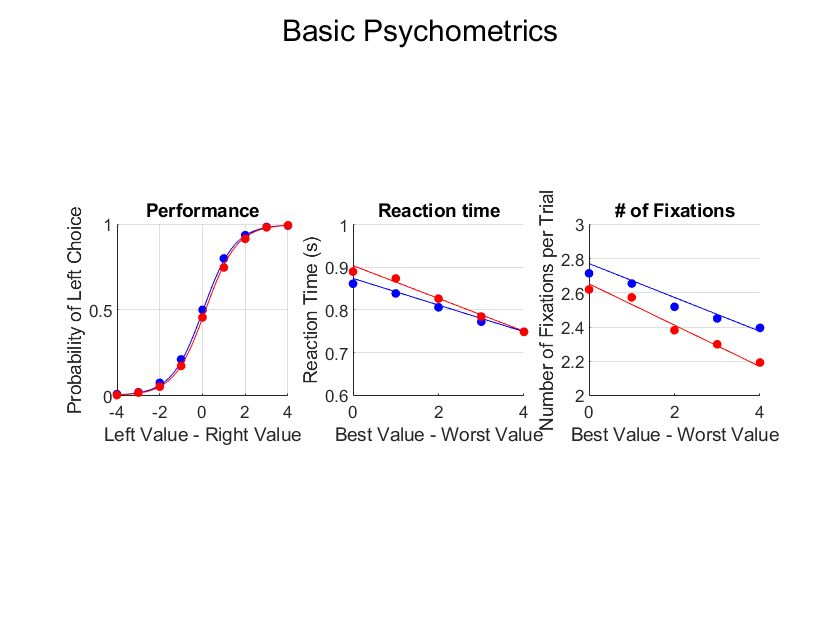

% define monk-specific variables
monks = {"MonkeyC","MonkeyK"};
colors = {'b','r'};
idx = [1:81; 82:162];
idx2 = [1:41; 42:82];

% break choice down by monk, vDiff, and session. This should generate one
% value for each session x vDiff x monk

% choice
choices = grpstats(psychometrics,{'session','vDiff','monk'},{'mean'},...
    'DataVars','chosen');

% group above stats to get 1 value for each value difference, for each monk (9x2 values total)
choices2 = grpstats(choices,{'vDiff','monk'},{'mean','sem'},...
    'DataVars',{'mean_chosen'});


rtFix = grpstats(psychometrics,{'session','diffic','monk'},{'mean'},...
    'DataVars',{'liftRT','totFix'});
rtfix2 = grpstats(rtFix,{'diffic','monk'},{'mean','sem'},...
    'DataVars',{'mean_liftRT','mean_totFix'});

% generate table table to be used for model fit line

% choice
xPred = table([-4:0.1:4]',psychometrics.totFix(1:81),psychometrics.liftRT(1:81),psychometrics.monk(1:81), psychometrics.diffic(1:81), 'VariableNames',{'vDiff','totFix','liftRT','monk','diffic'});
xPred = [xPred;xPred];
xPred.monk(82:end) = "MonkeyK";
choiceYhat = predict(choice, xPred);
xChoice = linspace(-4,4,81)';


% rt & fix
xPred2 = table([0:0.1:4]',psychometrics.totFix(1:41),psychometrics.liftRT(1:41),psychometrics.monk(1:41), psychometrics.vDiff(1:41), 'VariableNames',{'diffic','totFix','liftRT','monk','vDiff'});
xPred2 =[xPred2;xPred2];
xPred2.monk(42:end) = "MonkeyK";
rtYhat = predict(rt, xPred2);
fixYhat = predict(fix, xPred2);
xRtFix = linspace(0,4,41)';

clf
for monk = 1:2
    % choice curve
    subplot(1,3,1)
    plot(-4:4,choices2(choices2.monk == monks{monk},:).mean_mean_chosen,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xChoice,choiceYhat(idx(monk,:)),'color',colors{monk},'LineWidth',0.5)
    xlabel('Left Value - Right Value')
    ylabel('Probability of Left Choice')
    set(gca,'XGrid',1,'YGrid',1)
    xlim([-4 4])
    yticks([0 0.5 1])
    title('Performance')
    pbaspect([1 1 1])
    box off
    
    
    % rt curve
    subplot(1,3,2)
    plot(0:4,rtfix2(rtfix2.monk == monks{monk},:).mean_mean_liftRT,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xRtFix,rtYhat(idx2(monk,:)),'color',colors{monk},'LineWidth',0.5)
    ylim([0.6 1])
    xlabel('Best Value - Worst Value')
    ylabel('Reaction Time (s)')
    title('Reaction time')
    set(gca,'YGrid',1)
    pbaspect([1 1 1])
    box off
    
    % fix curve
    subplot(1,3,3)
    plot(0:4,rtfix2(rtfix2.monk == monks{monk},:).mean_mean_totFix,[colors{monk}, '.'],'MarkerSize',15); hold on 
    plot(xRtFix,fixYhat(idx2(monk,:)),'color',colors{monk},'LineWidth',0.5)
    xlabel('Best Value - Worst Value')
    ylabel('Number of Fixations per Trial')
    ylim([2 3])
    title('# of Fixations')
    yticks([2:0.2:3])
    set(gca,'YGrid',1)
    pbaspect([1 1 1])
    box off
end
sgtitle('Basic Psychometrics')

## Fixation Properties 

### Initial Fixation

Explain the duration of the initial fixation as a function of the value of the first fixated target

Variables

- firstFixDur = duration of the initial fixation

- firstFixVal = value of the first-fixated target

- monk = monkey identifier

% Mixed effects model
initVal = fitglme(initialFix,'firstFixDur ~ firstFixVal +(1 + firstFixVal|monk)','Distribution','Normal')

initVal = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           30357
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    firstFixDur ~ 1 + firstFixVal + (1 + firstFixVal | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -78102    -78052    39057            -78114  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF       pValue      Lower        Upper   
    {'(Intercept)'}         0.15991    0.0015285    104.62    30355           0      0.15691      0.1629
    {'firstFixVal'}        0.014865     0.006126    2.4265    30355    0.015252    0.00285


% run anova on the output of the model
anova(initVal)

ans =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue  
    {'(Intercept)'}         10944    1      30355           0
    {'firstFixVal'}        5.8878    1      30355    0.015252


### Middle Fixations

Explain the duration of middle fixations as a function of the value of the target being fixated

- MFDur = duration of the initial fixation

- MFVal = value of the first-fixated target

- monk = monkey identifier

% Mixed effects model
MFval = fitglme(middleFix,'MFdur ~ MFVal +(1 + MFVal|monk)','Distribution','Normal')

MFval = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           18085
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    MFdur ~ 1 + MFVal + (1 + MFVal | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -41961    -41914    20987            -41973  

Fixed effects coefficients (95% CIs):
    Name                   Estimate      SE            tStat      DF       pValue         Lower         Upper     
    {'(Intercept)'}            0.2183     0.0088597     24.639    18083    7.1538e-132       0.20093       0.23566
    {'MFVal'      }        -0.0078691    0.00048808    -16.123    18083     4.4976e-58    


% run anova on the output of the model
MFvalAnova = anova(MFval)

MFvalAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue     
    {'(Intercept)'}        607.08    1      18083    7.1538e-132
    {'MFVal'      }        259.94    1      18083     4.4976e-58


Explain the duration of middle fixations as a function of the trial difficulty

- MFDur = duration of the initial fixation

- MFdiff = trial difficulty

- monk = monkey identifier

% Mixed effects model
MFrelVal =  fitglme(middleFix,'MFdur ~ MFrelVal +(1 + MFrelVal|monk)','Distribution','Normal')

MFrelVal = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           18085
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    MFdur ~ 1 + MFrelVal + (1 + MFrelVal | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -43717    -43670    21864            -43729  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE           tStat     DF       pValue        Lower       Upper   
    {'(Intercept)'}         0.21506     0.011663     18.44    18083    3.0857e-75      0.1922     0.23792
    {'MFrelVal'   }        0.017405    0.0023162    7.5146    18083    5.9724e-14    0.012865    0.


% run anova on the output of the model
MFrelValAnova = anova(MFrelVal)

MFrelValAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        340.02    1      18083    3.0857e-75
    {'MFrelVal'   }         56.47    1      18083    5.9724e-14


Explain the duration of middle fixations as a function of the trial difficulty

- MFDur = duration of the initial fixation

- MFRelVal = value of the fixated item - value of unfixated item

- monk = monkey identifier

% Mixed effects model
MFdiff =  fitglme(middleFix,'MFdur ~ MFdiff +(1 + MFdiff|monk)','Distribution','Normal')

MFdiff = Generalized linear mixed-effects model fit by PL

Model information:
    Number of observations           18085
    Fixed effects coefficients           2
    Random effects coefficients          4
    Covariance parameters                4
    Distribution                    Normal
    Link                            Identity
    FitMethod                       MPL   

Formula:
    MFdur ~ 1 + MFdiff + (1 + MFdiff | monk)

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    -43028    -42982    21520            -43040  

Fixed effects coefficients (95% CIs):
    Name                   Estimate     SE           tStat      DF       pValue        Lower        Upper    
    {'(Intercept)'}           0.2263     0.012473     18.143    18083    6.4623e-73      0.20185      0.25075
    {'MFdiff'     }        -0.020056    0.0025094    -7.9922    18083    1.4052e-15    -0.024975 


% run anova on the output of the model
MFdiffAnova = anova(MFdiff)

MFdiffAnova =     ANOVA marginal tests: DFMethod = 'residual'

    Term                   FStat     DF1    DF2      pValue    
    {'(Intercept)'}        329.17    1      18083    6.4623e-73
    {'MFdiff'     }        63.875    1      18083    1.4052e-15
